# Ajustement des paramètres de collision

## Probability of collision during a time step $dt$

Travel distance of a particle $i$ during a time step $dt$: 


$$\delta_i = u_idt + dK_idt + R_i\sqrt{\frac{2}{d}K_idt}$$


With $R_i \sim N(0,\, \sqrt{d})$. But as $X \sim N(\mu,\,\sigma) \Rightarrow aX+b \sim N(a\mu+b,\, \|a\|\sigma)$, we can say that :


$$\delta_i \sim N\left(u_idt + dK_idt,\; \sqrt{2K_idt}\right)$$


Let $\delta_{21} = \delta_2-\delta_1$, the travel distance of a particle $2$, taking a particle $1$ as reference. We then have :


$$\delta_2 \sim N\left(u_2dt + dK_2dt,\; \sqrt{2K_2dt}\right)$$



$$-\delta_1 \sim N\left(-u_1dt - dK_1dt,\; \sqrt{2K_1dt}\right)$$


$N$ is stable through addition : if $X_A \sim N(\mu_A,\sigma_A)$ and $X_B \sim N(\mu_B,\sigma_B)$ are two independents variables, we have $X_A + X_B \sim N(\mu_A + \mu_B,\sqrt{\sigma_A^2+\sigma_B^2})$. Hence : 


$$\delta_{21} \sim N\left([u_2-u_1 + dK_2-dK_1]dt,\; \sqrt{2dt[K_1 + K_2]}\right)$$


Let $\Delta z_{21}^t$ the position of particle $2$ with particle $1$ as reference at time $t$. At $t+dt$, $\Delta z_{21}^{t+dt} = \Delta z_{21}^t + \delta_{21}$.


$$\Delta z_{21}^{t+dt} \sim N\left( [u_2-u_1 + dK_2-dK_1]dt + \Delta z_{21}^t,\; \sqrt{2dt[K_1 + K_2]} \right)$$


Let $p(\Delta z_{21}^t,\: dt)$ the probability of collision during the next time step $dt$ between the particles $1$ and $2$ being separated by a distance $\Delta z_{21}^t$ at time $t$ and of diameter $d_1$ and $d_2$. 

### If $\Delta z_{21}^t \in ]-\infty ; -\frac{d_1+d_2}{2}[$


$$(\Delta z_{21}^t,\: dt) = P(\Delta z_{21}^{t+dt} \geq -\frac{d_1+d_2}{2}) = 1-P(\Delta z_{21}^{t+dt} < -\frac{d_1+d_2}{2})$$


### If $\Delta z_{21}^t \in ]\frac{d_1+d_2}{2} ; \infty[$


$$p(\Delta z_{21}^t,\: dt) = P(\Delta z_{21}^{t+dt} \leq \frac{d_1+d_2}{2})$$


### If $\Delta z_{21}^t \in ]-\frac{d_1+d_2}{2} ; \frac{d_1+d_2}{2}[$


$$p(\Delta z_{21}^t,\: dt) = 1$$


## Obtention des données de collision

$z^{t-dt}$ est retenu pour chaque particule à chaque pas de temps. Si une collision a lieu à $t$, on garde en mémoire $\Delta z^{t-dt}$.

À la fin de la simulation on trace l'histogrames des $\Delta z^{t-dt}$ ayant conduit à une collision à $t$.

Pour rendre les résultats plus interprétables, on initialise un agrégat qui restera fixe durant toute la simulation et $n$ MPs uniformément répartis dans un rayon de $0.1m$ autour de l'agrégat. 

Deux simulations sont réalisées : une avec le modèle dévellopé avec un pas de temps $dt_m$ et une modélisant les collisions réelles, dont le pas de temps $dt_{RC}$ respecte la condition $dt_{RC} \leq dt_{max}$ pour ne pas ratter de collisions avec un pas de temps trop grand.

clear,

dt_test = 0.00001;
date = datetime(2020,03,18);
tf = 0.1;

dtTheoB = tf;
% dt_testB = dtTheoB/2;

%% Water column parameters
% Find depth of the column
load('../Data/2020waterCol_RN2.mat', 'H0')
L = H0; % depth
clear H0,

N = 20;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 1e3;
% pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
% sizeMP = random(pd,nMP,1);
% sizeMP(sizeMP<1e-6) = 1e-6;
% clear pd,
sizeMP = ones(nMP,1)*450e-6;
zInitMP = linspace(29.9,30.1,nMP);
% zInitMP = ones(nMP,1)*30.5;
rhoMP = 1000;

nAgg = 1;
% pd = makedist('Normal', 'mu', 2e-2, 'sigma', 1e-2);
% sizeAgg = random(pd,nAgg,1);
% sizeAgg(sizeAgg<1e-6) = 1e-6;
sizeAgg = ones(nAgg,1)*1e-3;
% clear pd,
% zInitAgg = linspace(30,31,nAgg);
zInitAgg = 30;
rhoAgg = 1040;

wind = 50;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
K = 0.01*ones(size(K));
dK = zeros(size(dK));
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
        agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,



--------------------- Simulation running ---------------------


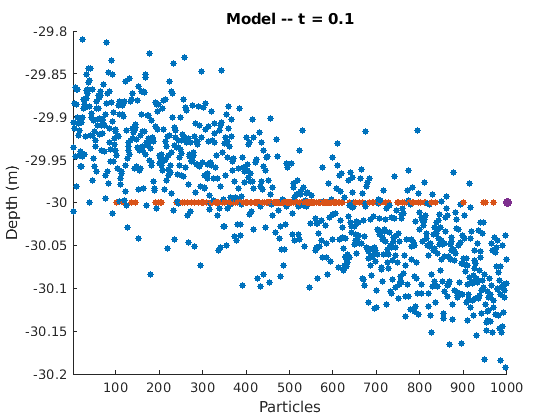

path = '../Results/Aggr/';
nameMat = [ 'm_' num2str(tf) 's_cstK.mat'];

[collisionB, dtB,mpZB,aggZB,mpListB,aggListB] = Part_SimulatorBoom(mp_list,...

    agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtTheoB);
save([path 'collisionB_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat], 'collisionB', 'dtB','mpZB','aggZB','mpListB','aggListB')

colTestB = cell2mat(collisionB');   
DataColB = colTestB(:,1);

clear colTestB collisionB aggListB mpListB,



--------------------- Simulation running ---------------------


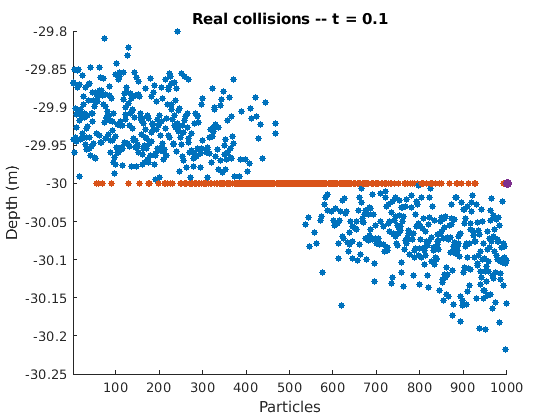

[collisionA, dtA,mpZA,aggZA,mpListA,aggListA] = Collision_Simulator(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtB);

save([path 'collisionA_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat],...
    'collisionA', 'dtA','mpZA','aggZA','mpListA','aggListA')

colTestA = cell2mat(collisionA');
DataColA = colTestA(:,1);

clear colTestA  collisionA  aggListA   mpListA  ,

On représente la probabilité de collision en un temps $dt$ obtenue pour les collisions réelles et notre modèle. Une loie normale est ensuite ajustée aux répartitions de probabilité obtenues pour chaque modèle.

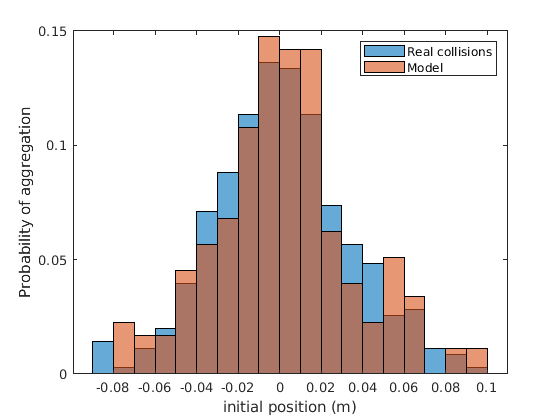

hA = histogram(DataColA,'Normalization','probability','BinWidth', 0.01,...
   'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'Normalization','probability' ,'BinEdges',hA.BinEdges,...
    'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Probability of aggregation")

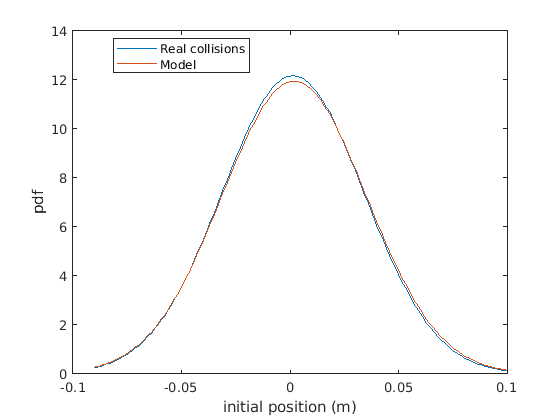


% pd = makedist('Normal',"mu",0,"sigma",std(DataCol));
% pdFit = fitdist(DataCol,'Kernel')
% % gaussienneTest = pdf(pd,h.BinEdges);
% gaussienneFit = pdf(pdFit,h.BinEdges);
% % plot(h.BinEdges,gaussienneTest)
% plot(h.BinEdges,gaussienneFit)
% hold off,
fitA = fitdist(DataColA,'Normal');
fitB = fitdist(DataColB,'Normal');
xfit = hA.BinLimits(1):1e-3:hA.BinLimits(2);


plot(xfit,pdf(fitA,xfit),'DisplayName','Real collisions')
hold on,
plot(xfit,pdf(fitB,xfit),'DisplayName','Model')
hold off,
% xline((mean(sizeAgg)+mean(sizeMP))/2)
legend('Location','best')
xlabel('initial position (m)')
ylabel("pdf")

rmsePdfInit = sqrt(mean((pdf(fitB,xfit)-pdf(fitA,xfit)).^2))

rmsePdfInit = 0.1246

On peut voir qu'on obtient une répartition de probabilité pour le modèle proche de celle pour les collisions réelles.

Nombre de collisions en fonction de la distance initiale à l'agrégat

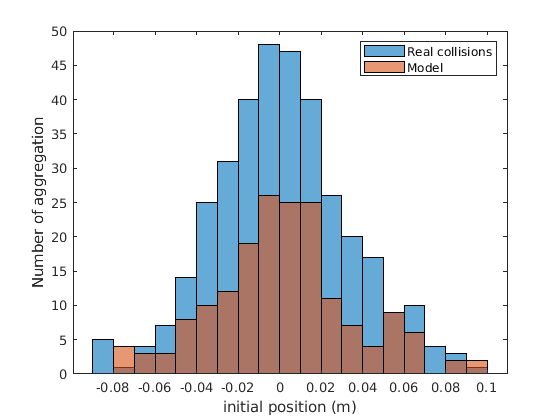

hA = histogram(DataColA,'BinWidth', 0.01, 'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'BinEdges',hA.BinEdges,'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

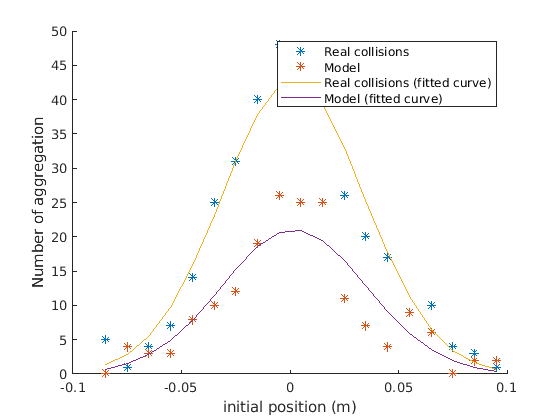

xA = hA.BinEdges(1:end-1)+hA.BinWidth/2;
yA = hA.Values;
xB = hB.BinEdges(1:end-1)+hB.BinWidth/2;
yB = hB.Values;
dxA = hA.BinWidth;
dxB = hB.BinWidth;


clf, hold on,
plot(xA,yA,'*','DisplayName','Real collisions')
plot(xB,yB,'*','DisplayName','Model')

plot(xA,pdf(fitA,xA).*dxA.*numel(DataColA),'DisplayName',['Real collisions' ...
    '(fitted curve)'])
plot(xB,pdf(fitB,xB).*dxB.*numel(DataColB),'DisplayName','Model (fitted curve)')

hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

rmseNInit = sqrt(mean((pdf(fitB,xB).*dxB.*numel(DataColB)...

rmseNInit = 11.9532

    -pdf(fitA,xA).*dxA.*numel(DataColA)).^2))

Malgrès des répartitions de probabilité proches, le nombre de collisions en fonction de la distance initiale est bien inférieur aux collisions réelles. On sous-estime donc toujours le nombre de collisions dans l'estimation des collisions.

Soit $\gamma$ le facteur multiplicatif entre le modèle et les collisions réelles.

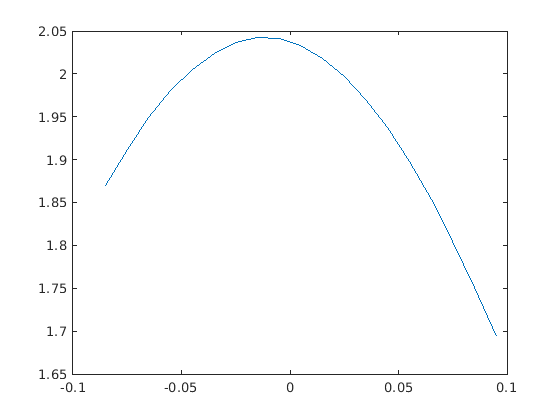

xDiff = -0.2

gamma_dt = pdf(fitA,xA).*dxA.*numel(DataColA)./(pdf(fitB,xB)...
    .*dxB.*numel(DataColB));
plot(xA,gamma_dt)

On va chercher comment évolue $\gamma$ pour différentes valeurs de $K$ et $dt$.

## Évolution du facteur $\gamma$ en fonction des paramètres $K$ et $dt$

Les résultats des deux modèles pour différentes valeurs de $K$ et $dt$ sont comparées pour chercher à caractériser l'évolution de $\gamma$ en fonction de $dtK$.

clear,
load('/media/ian/Transcend/MPsDistrib/Results/Aggr/dtK_collision_sort_data.mat')
load('/media/ian/Transcend/MPsDistrib/Results/Aggr/dtK_collision_data_sort2.mat')

dzInit = 0.01;
initDistBin = -0.1:dzInit:0.1;
initDistBin_ = (initDistBin(1:end-1)+initDistBin(2:end))./2;

gamma = nan(length(dtK_sort),length(initDistBin_));
gammaMean = nan(length(dtK_sort),1);
rmse = nan(length(dtK_sort),1);
stdRatio = nan(length(dtK_sort),1);

gamma2 = nan(length(dtK_sort),length(initDistBin_));
gammaMean2 = nan(length(dtK_sort),1);
rmse2 = nan(length(dtK_sort),1);
stdRatio2 = nan(length(dtK_sort),1);

for i = 1:length(dtK_sort)
    DataColA = dtK_collisions_sort{i,1};
    DataColB = dtK_collisions_sort{i,2};
    fitA = fitdist(DataColA,'Normal');
    fitB = fitdist(DataColB,'Normal');
    gammaMean(i) = numel(DataColA)/numel(DataColB);
    stdRatio(i) = fitB.sigma/fitA.sigma;
    rmse(i,1) = sqrt(sum((pdf(fitA,initDistBin_).*dzInit.*numel(DataColA)...
        -(pdf(fitB,initDistBin_).*dzInit.*numel(DataColB))).^2));
    
    DataColA2 = dtK_collisions_sort2{i,1};
    DataColB2 = dtK_collisions_sort2{i,2};
    fitA2 = fitdist(DataColA2,'Normal');
    fitB2 = fitdist(DataColB2,'Normal');
    gammaMean2(i) = numel(DataColA2)/numel(DataColB2);
    stdRatio2(i) = fitB2.sigma/fitA2.sigma;
    rmse2(i,1) = sqrt(sum((pdf(fitA2,initDistBin_).*dzInit.*numel(DataColA2)...
        -(pdf(fitB2,initDistBin_).*dzInit.*numel(DataColB2))).^2));
    
end

#### Gamma

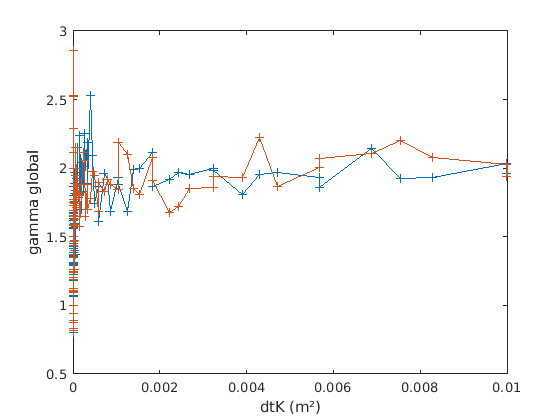

plot(dtK_sort,gammaMean,'-+', dtK_sort,gammaMean2,'-+')
xlabel('dtK (m²)')
ylabel('gamma global')

L'évolution de $\gamma$semble se stabiliser rapidement avec l'augmentation de $dtK$.

xfit = [log(dtK_sort');log(dtK_sort')];
xfit2 = [log(sqrt(dtK_sort'));log(sqrt(dtK_sort'))];
yfit = [gammaMean;gammaMean2];
X = [ones(length(xfit),1) xfit];
X2 = [ones(length(xfit2),1) xfit2];
b = X\yfit

b =     2.5160
    0.0834


b2 = X2\yfit

b2 =     2.5160
    0.1669


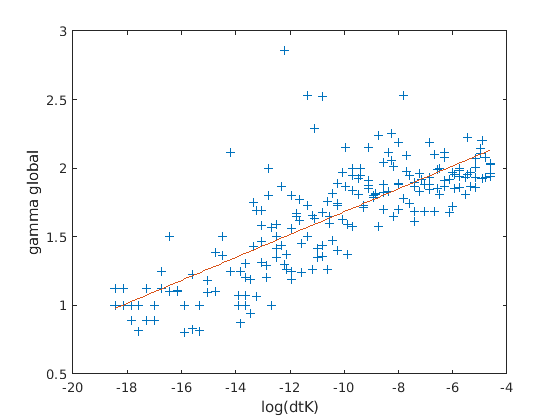


xplot = linspace(min(xfit),max(xfit),100);
yplot = xplot*b(2)+b(1);

plot(xfit,yfit,'+',xplot,yplot)
xlabel('log(dtK)')
ylabel('gamma global')

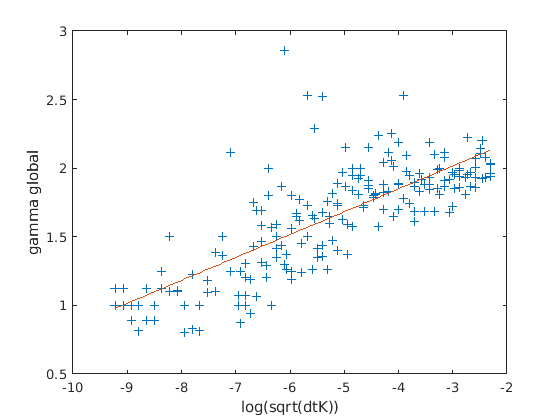

xplot2 = linspace(min(xfit2),max(xfit2),100);
yplot2 = xplot2*b2(2)+b2(1);

plot(xfit2,yfit,'+',xplot2,yplot2)
xlabel('log(sqrt(dtK))')
ylabel('gamma global')

$\gamma$ semble évoluer selon une loi affine en fonction de $log(dtK)$ et de $log(\sqrt{dtK})$. Les coefficients de ces relations sont estimées par méthode des moindres carrés et comparés aux valeurs de $\gamma$ ($R^2$).

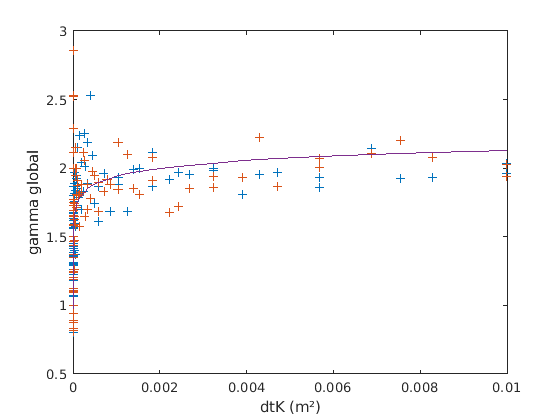


gammaCalc1 = b(2).*log(dtK_sort)+b(1);
gammaCalc2 = b2(2).*log(sqrt(dtK_sort))+b2(1);

plot(dtK_sort,gammaMean,'+',dtK_sort,gammaMean2,'+', dtK_sort,gammaCalc1,'-',...
    dtK_sort,gammaCalc2,'-')
xlabel('dtK (m²)')
ylabel('gamma global')

Rsq1 = 1 - sum((gammaMean - gammaCalc1').^2+(gammaMean2 - gammaCalc1').^2)...

Rsq1 = 0.5895

    /sum((yfit - mean(yfit)).^2)
Rsq2 = 1 - sum((gammaMean - gammaCalc2').^2+(gammaMean2 - gammaCalc2').^2)...

Rsq2 = 0.5895

    /sum((yfit - mean(yfit)).^2)

Les deux lois affines sont très proches et ont la même valeur de $R^2$.

$\gamma = \alpha ln(dt K) + \beta$ avec $\alpha = 0.0834$ et $\beta = 2.516$

# Collision test with adjusted probability

Les tests initiaux sont reévalués avec l'ajustement du coefficient $\gamma$.

## Immobile aggregate

clear,

dt_test = 0.00001;
date = datetime(2020,03,18);
tf = 1;

dtTheoB = tf;
% dt_testB = dtTheoB/2;

%% Water column parameters
% Find depth of the column
load('../Data/2020waterCol_RN2.mat', 'H0')
L = H0; % depth
clear H0,

N = 20;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 1e3;
% pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
% sizeMP = random(pd,nMP,1);
% sizeMP(sizeMP<1e-6) = 1e-6;
% clear pd,
sizeMP = ones(nMP,1)*450e-6;
zInitMP = linspace(29.9,30.1,nMP);
% zInitMP = ones(nMP,1)*30.5;
rhoMP = 1000;

nAgg = 1;
% pd = makedist('Normal', 'mu', 2e-2, 'sigma', 1e-2);
% sizeAgg = random(pd,nAgg,1);
% sizeAgg(sizeAgg<1e-6) = 1e-6;
sizeAgg = ones(nAgg,1)*1e-3;
% clear pd,
% zInitAgg = linspace(30,31,nAgg);
zInitAgg = 30;
rhoAgg = 1040;

wind = 50;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
K = 0.01*ones(size(K));
dK = zeros(size(dK));
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
        agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,



--------------------- Simulation running ---------------------


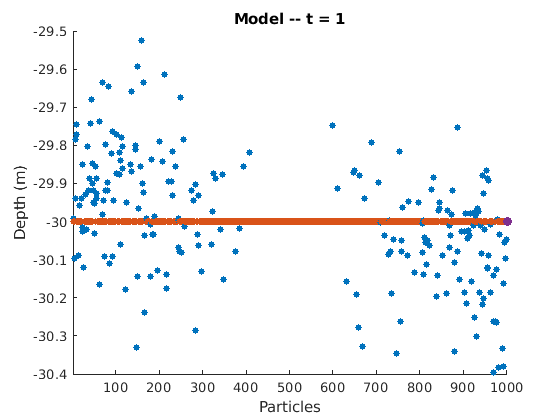

path = '../Results/Aggr/';
nameMat = [ 'm_' num2str(tf) 's_cstK_gamma.mat'];

[collisionB, dtB,mpZB,aggZB,mpListB,aggListB] = Part_SimulatorBoom(mp_list,...

    agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtTheoB);
save([path 'collisionB_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat],...
    'collisionB', 'dtB','mpZB','aggZB','mpListB','aggListB')

colTestB = cell2mat(collisionB');   
DataColB = colTestB(:,1);

clear colTestB collisionB aggListB mpListB,



--------------------- Simulation running ---------------------


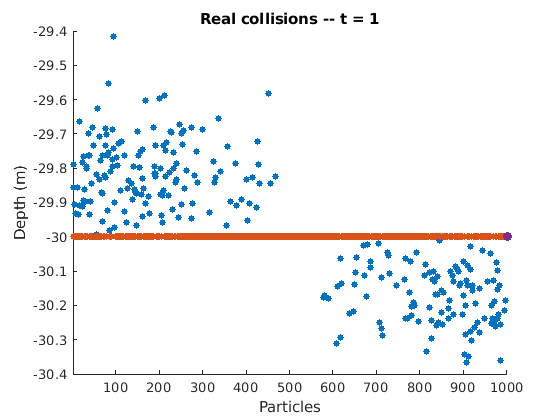

[collisionA, dtA,mpZA,aggZA,mpListA,aggListA] = Collision_Simulator(mp_list,...

    agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtB);
save([path 'collisionA_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat],...
    'collisionA', 'dtA','mpZA','aggZA','mpListA','aggListA')

colTestA = cell2mat(collisionA');
DataColA = colTestA(:,1);

clear colTestA  collisionA  aggListA   mpListA  ,

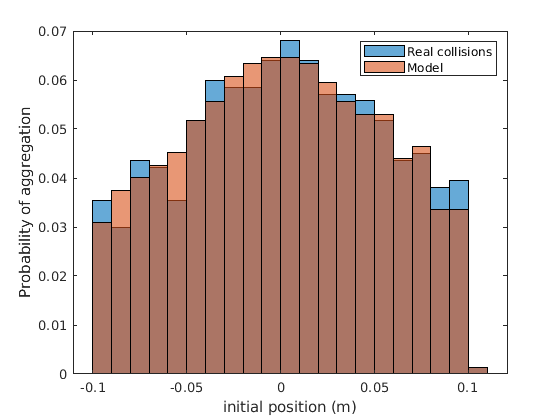

hA = histogram(DataColA,'Normalization','probability','BinWidth', 0.01,...
    'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'Normalization','probability' ,'BinEdges',hA.BinEdges,...
    'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Probability of aggregation")

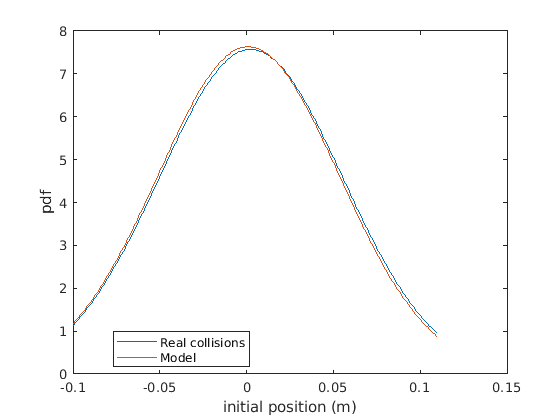


% pd = makedist('Normal',"mu",0,"sigma",std(DataCol));
% pdFit = fitdist(DataCol,'Kernel')
% % gaussienneTest = pdf(pd,h.BinEdges);
% gaussienneFit = pdf(pdFit,h.BinEdges);
% % plot(h.BinEdges,gaussienneTest)
% plot(h.BinEdges,gaussienneFit)
% hold off,
fitA = fitdist(DataColA,'Normal');
fitB = fitdist(DataColB,'Normal');
xfit = hA.BinLimits(1):1e-3:hA.BinLimits(2);


plot(xfit,pdf(fitA,xfit),'DisplayName','Real collisions')
hold on,
plot(xfit,pdf(fitB,xfit),'DisplayName','Model')
hold off,
% xline((mean(sizeAgg)+mean(sizeMP))/2)
legend('Location','best')
xlabel('initial position (m)')
ylabel("pdf")

rmsePdfGamma = sqrt(mean((pdf(fitB,xfit)-pdf(fitA,xfit)).^2))

rmsePdfGamma = 0.1023

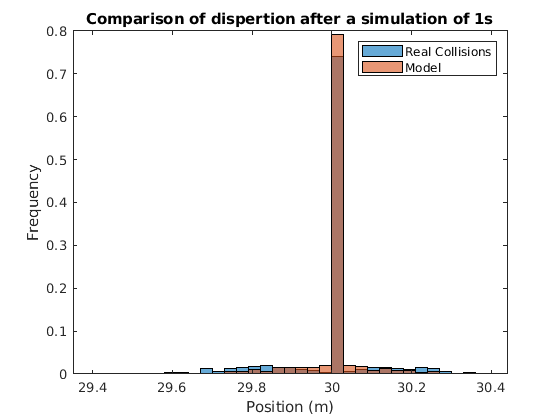

zHA = histogram(mpZA,'Normalization','probability',"DisplayName",'Real Collisions');
hold on,
zHB = histogram(mpZB,'Normalization','probability', 'BinEdges', zHA.BinEdges,...
    "DisplayName",'Model');
hold off
legend
title(['Comparison of dispertion after a simulation of ' num2str(tf) 's'])
xlabel('Position (m)')
ylabel('Frequency')

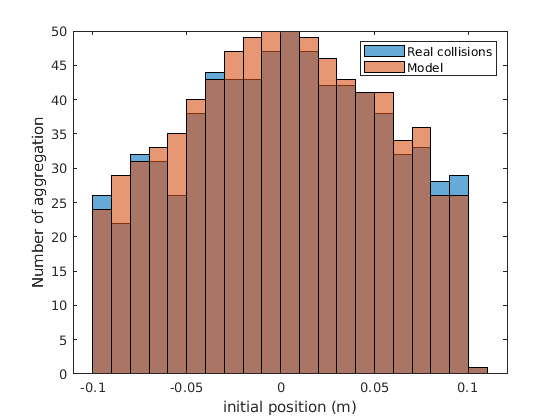

hA = histogram(DataColA,'BinWidth', 0.01, 'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'BinEdges',hA.BinEdges,'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

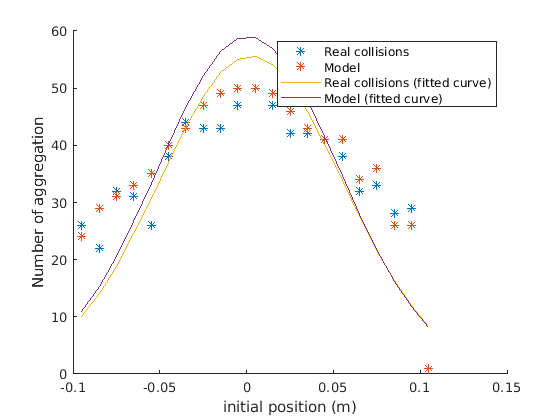

xA = hA.BinEdges(1:end-1)+hA.BinWidth/2;
yA = hA.Values;
xB = hB.BinEdges(1:end-1)+hB.BinWidth/2;
yB = hB.Values;
dxA = hA.BinWidth;
dxB = hB.BinWidth;


clf, hold on,
plot(xA,yA,'*','DisplayName','Real collisions')
plot(xB,yB,'*','DisplayName','Model')

plot(xA,pdf(fitA,xA).*dxA.*numel(DataColA),'DisplayName',...
    'Real collisions (fitted curve)')
plot(xB,pdf(fitB,xB).*dxB.*numel(DataColB),'DisplayName','Model (fitted curve)')

hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

rmseNGamma = sqrt(mean((pdf(fitB,xB).*dxB.*numel(DataColB)...

rmseNGamma = 2.2574

    -pdf(fitA,xA).*dxA.*numel(DataColA)).^2))

Les deux distributions de probabilité sont toujours aussi proches et les nombres de collisions sont bien plus proches que précédement. 

## All particles can move

Même tests mais avec plusieurs agrégats pouvant se déplacer librement dans la colone d'eau.

clear,

dt_test = 0.00001;
date = datetime(2020,03,18);
tf = 1;

dtTheoB = tf;
% dt_testB = dtTheoB/2;

%% Water column parameters
% Find depth of the column
load('../Data/2020waterCol_RN2.mat', 'H0')
L = H0; % depth
clear H0,

N = 20;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 1000;
sizeMP = ones(nMP,1)*450e-6;
zInitMP = rand(1,nMP)*L;
% zInitMP = ones(nMP,1)*30.5;
rhoMP = 1000;

nAgg = 10;
% pd = makedist('Normal', 'mu', 2e-2, 'sigma', 1e-2);
% sizeAgg = random(pd,nAgg,1);
% sizeAgg(sizeAgg<1e-6) = 1e-6;
sizeAgg = ones(nAgg,1)*1e-3;
% clear pd,
zInitAgg = rand(1,nAgg)*L;
% zInitAgg = 30;
rhoAgg = 1040;

wind = 50;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
        agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,



--------------------- Simulation running ---------------------


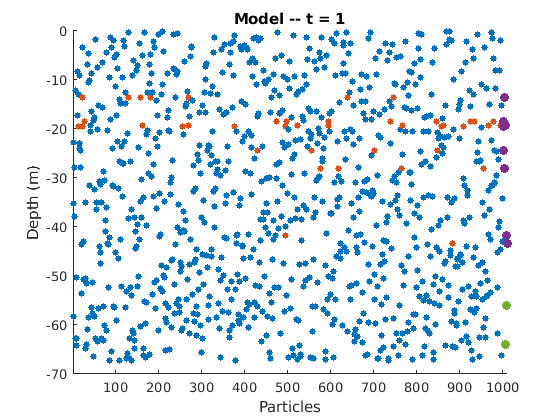

path = '../Results/Aggr/';
nameMat = [ 'm_' num2str(tf) 's_allMoving.mat'];

[collisionB, dtB,mpZB,aggZB,mpListB,aggListB] = Part_SimulatorBoom(mp_list,...

    agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtTheoB);
save([path 'collisionB_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat],...
    'collisionB', 'dtB','mpZB','aggZB','mpListB','aggListB')

colTestB = cell2mat(collisionB');   
DataColB = colTestB(:,1);

clear colTestB collisionB aggListB mpListB,



--------------------- Simulation running ---------------------


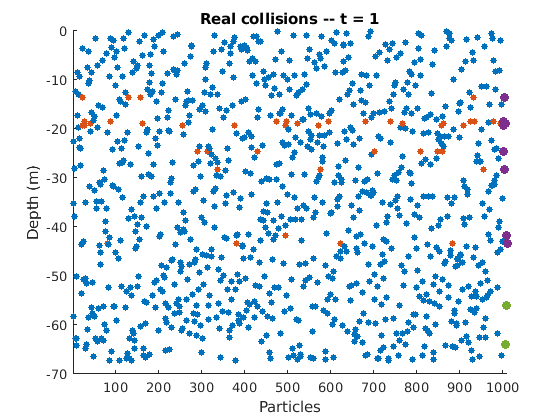

[collisionA, dtA,mpZA,aggZA,mpListA,aggListA] = Collision_Simulator(mp_list,...

    agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtB);
save([path 'collisionA_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat],...
    'collisionA', 'dtA','mpZA','aggZA','mpListA','aggListA')

colTestA = cell2mat(collisionA');
DataColA = colTestA(:,1);

clear colTestA  collisionA  aggListA   mpListA  ,

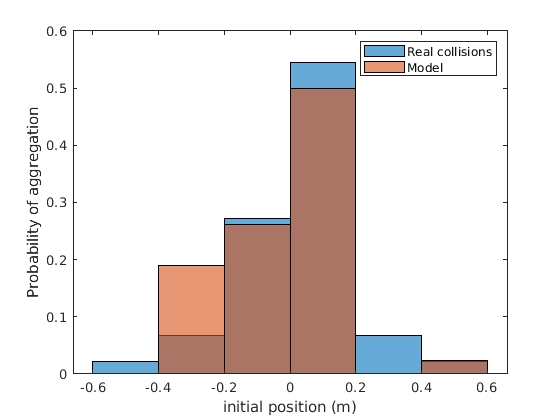

hA = histogram(DataColA,'Normalization','probability', 'DisplayName',...
    'Real collisions');
hold on,
hB = histogram(DataColB,'Normalization','probability' ,'BinEdges',hA.BinEdges,...
    'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Probability of aggregation")

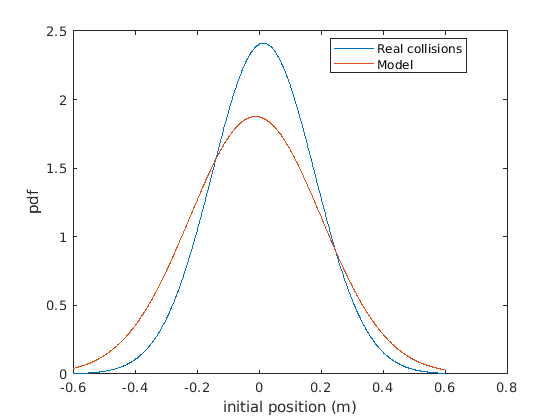


% pd = makedist('Normal',"mu",0,"sigma",std(DataCol));
% pdFit = fitdist(DataCol,'Kernel')
% % gaussienneTest = pdf(pd,h.BinEdges);
% gaussienneFit = pdf(pdFit,h.BinEdges);
% % plot(h.BinEdges,gaussienneTest)
% plot(h.BinEdges,gaussienneFit)
% hold off,
fitA = fitdist(DataColA,'Normal');
fitB = fitdist(DataColB,'Normal');
xfit = hA.BinLimits(1):1e-3:hA.BinLimits(2);


plot(xfit,pdf(fitA,xfit),'DisplayName','Real collisions')
hold on,
plot(xfit,pdf(fitB,xfit),'DisplayName','Model')
hold off,
% xline((mean(sizeAgg)+mean(sizeMP))/2)
legend('Location','best')
xlabel('initial position (m)')
ylabel("pdf")

rmsePdf = sqrt(mean((pdf(fitB,xfit)-pdf(fitA,xfit)).^2))

rmsePdf = 0.2629

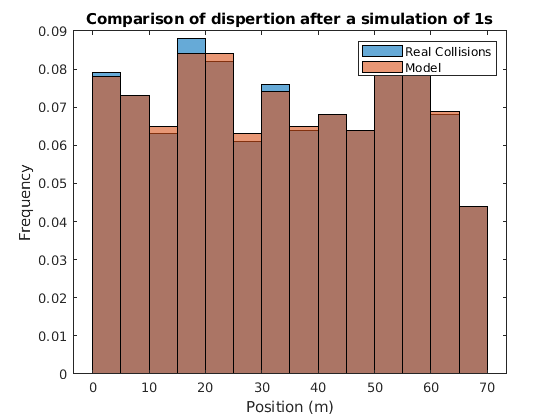

zHA = histogram(mpZA,'Normalization','probability',"DisplayName",...
    'Real Collisions');
hold on,
zHB = histogram(mpZB,'Normalization','probability', 'BinWidth', zHA.BinWidth,...
    "DisplayName",'Model');
hold off
legend
title(['Comparison of dispertion after a simulation of ' num2str(tf) 's'])
xlabel('Position (m)')
ylabel('Frequency')

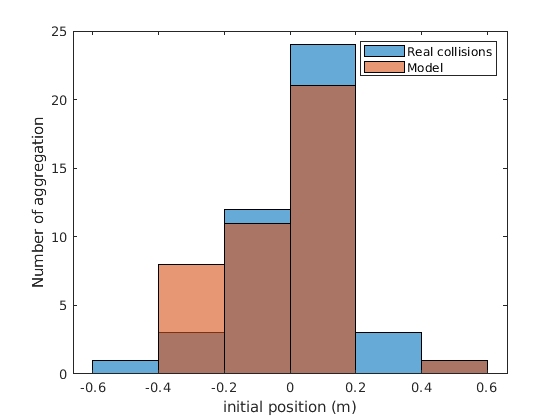

hA = histogram(DataColA, 'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'BinEdges',hA.BinEdges,'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

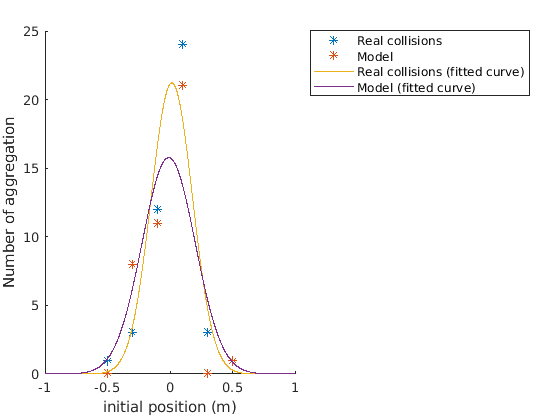

xA = hA.BinEdges(1:end-1)+hA.BinWidth/2;
yA = hA.Values;
xB = hB.BinEdges(1:end-1)+hB.BinWidth/2;
yB = hB.Values;
dxA = hA.BinWidth;
dxB = hB.BinWidth;


clf, hold on,
plot(xA,yA,'*','DisplayName','Real collisions')
plot(xB,yB,'*','DisplayName','Model')

xFit = -1:0.001:1;

plot(xFit,pdf(fitA,xFit).*dxA.*numel(DataColA),'DisplayName',...
    'Real collisions (fitted curve)')
plot(xFit,pdf(fitB,xFit).*dxB.*numel(DataColB),'DisplayName',...
    'Model (fitted curve)')

hold off,
legend('Location', 'bestoutside')
xlabel('initial position (m)')
ylabel("Number of aggregation")

rmseN = sqrt(mean((pdf(fitB,xFit).*dxB.*numel(DataColB)...

rmseN = 1.9598

    -pdf(fitA,xFit).*dxA.*numel(DataColA)).^2))

Les distributions de probabilités sont plus éloignées mais les collisions restent bien mieux qu'initialement. 